close all
clear variables

spectra = importdata("spectra.csv");
lambdaStart = importdata("lambda_start.csv");
lambdaDelta = importdata("lambda_delta.csv");
starNames = importdata("star_names.csv");

lambdaPr = 656.28 ; % нм
speedOfLight = 299792.458; % км/с

nObs = size(spectra, 1);
nStars = size(starNames, 1);
lamdbaEnd = lambdaStart + (nObs - 1) * lambdaDelta;
lambda = (lambdaStart:lambdaDelta:lamdbaEnd)';

speed = zeros(nStars, 1);
i = 1;
while i <= nStars
    s = spectra(:, i);
    [sHa, idx] = min(s);
    lambdaHa = lambda(idx);
    speed(i, 1) = ((lambdaHa / lambdaPr) - 1) * speedOfLight;
    i = i + 1;
end
movaway = starNames(speed > 0)

moveaway = 3×1 cell array
    {'HD5211' }
    {'HD56030'}
    {'HD94028'}


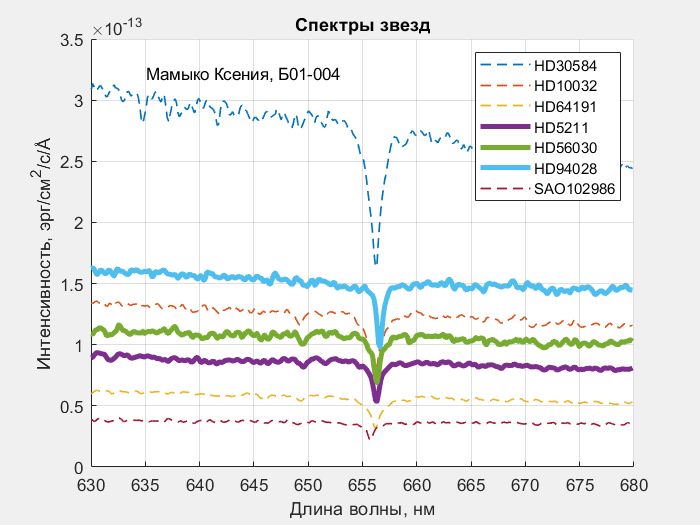

fg = figure;
set(fg, 'Visible', 'on');
xlabel('Длина волны, нм')
ylabel(['Интенсивность, эрг/см^2/c/',char(197)])
title({'Спектры звезд'})
hold on
grid on

for i = 1:1:nStars
    s = spectra(:, i);
    if speed(i, 1) > 0
        plot(lambda, s, 'LineWidth', 3)
    end
    if speed(i, 1) < 0
        plot(lambda, s,"--", 'LineWidth', 1)
    end   
end
legend(starNames, 'Location','northeast')
hold off
text(lambdaStart + 5, max(s)*8, 'Мамыко Ксения, Б01-004')
saveas(fg, 'spectra.png')